# Growth dependence on aromatic, sidechain, and backbone parameters

This script file opens a set of files of the form [fbase]+ AA-SC-BB '_runsmol-data-[cluster type].dat' that have a comment line starting with # and then another line that has 

#tc sigtc nltc nlsigtc lmbda siglmbda sse

white space separated on it.

For linear tc, nonlinear tc, and lambda, it extracts the value with the error and does a scatterplot where the axes are AA and SC (2D) and later it can be a 3D plot where the third axis is BB, if necessary, or another parameter.

Also plot all three with errors versus AA and versus SC

Data:

AA SC BB ltcC ltcCerr nltcC nltcCerr lmbdaC lmbdaCerr [same for O] [same for A]

## Read in Data

fileLocation = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/hoomd/patchy/analyze/';
AAnames = {'0','37','37','185','370','370','740','740'};
SCnames = {'10','0','02','10','4','10','0','10'};
BBnames = {'0','0','0','0','0','0','0','0'};
fbase = 'mols10000_';
paramMatrix = zeros(length(AAnames),3);
contactMatrix = zeros(length(AAnames),7);
opticalMatrix = zeros(length(AAnames),7);
alignedMatrix = zeros(length(AAnames),7);
for i = 1:length(AAnames)
    foldname = [fileLocation AAnames{i} '-' SCnames{i} '-' BBnames{i} '/'];
    fnameC = [foldname fbase AAnames{i} '-' SCnames{i} '-' BBnames{i} '_runsmol-data-contact.dat'];
    fnameO = [foldname fbase AAnames{i} '-' SCnames{i} '-' BBnames{i} '_runsmol-data-optical.dat'];
    fnameA = [foldname fbase AAnames{i} '-' SCnames{i} '-' BBnames{i} '_runsmol-data-aligned.dat'];
    dataC = importdata(fnameC,' ',1);
    dataO = importdata(fnameO,' ',1);
    dataA = importdata(fnameA,' ',1);
    paramMatrix(i,1) = str2double(AAnames{i})/100;
    paramMatrix(i,2) = str2double(SCnames{i})/100;
    paramMatrix(i,3) = str2double(BBnames{i})/100;
    for j = 1:7
       contactMatrix(i,j) = dataC.data(j);
       opticalMatrix(i,j) = dataO.data(j);
       alignedMatrix(i,j) = dataA.data(j);
    end
end
%set things that don't cluster to NaN
contactMatrix(2:3,:) = NaN;
opticalMatrix(2:3,:) = NaN;
alignedMatrix(2:3,:) = NaN;

## Make Scatterplot

**Contact Clusters**

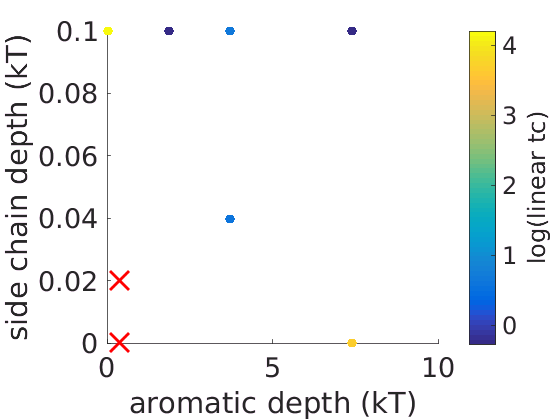

%linear tc
figure()
ginds = ~isnan(contactMatrix(:,1));
scatter(paramMatrix(ginds,1),paramMatrix(ginds,2),50,log(contactMatrix(ginds,1)),'filled')
hold on
plot(paramMatrix(isnan(contactMatrix(:,1)),1),paramMatrix(isnan(contactMatrix(:,1)),2),'rx','markersize',20,'linewidth',2)
set(gca,'fontsize',20)
xlabel('aromatic depth (kT)')
ylabel('side chain depth (kT)')
c = colorbar();
ylabel(c,'log(linear tc)')

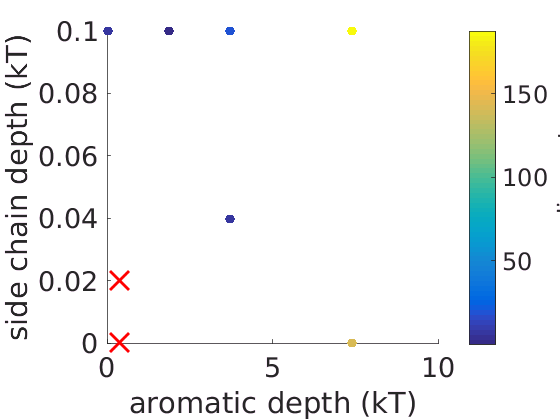


%nonlinear tc
figure()
ginds = ~isnan(contactMatrix(:,3));
scatter(paramMatrix(ginds,1),paramMatrix(ginds,2),50,contactMatrix(ginds,3),'filled')
hold on
plot(paramMatrix(isnan(contactMatrix(:,3)),1),paramMatrix(isnan(contactMatrix(:,3)),2),'rx','markersize',20,'linewidth',2)
set(gca,'fontsize',20)
xlabel('aromatic depth (kT)')
ylabel('side chain depth (kT)')
c = colorbar();
ylabel(c,'nonlinear tc')

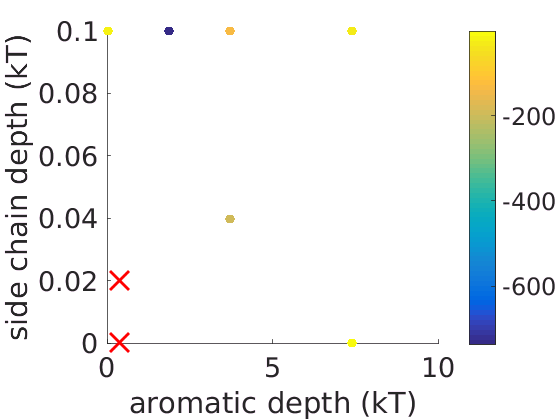


%lambda
figure()
ginds = ~isnan(contactMatrix(:,5));
scatter(paramMatrix(ginds,1),paramMatrix(ginds,2),50,contactMatrix(ginds,5),'filled')
hold on
plot(paramMatrix(isnan(contactMatrix(:,5)),1),paramMatrix(isnan(contactMatrix(:,5)),2),'rx','markersize',20,'linewidth',2)
set(gca,'fontsize',20)
xlabel('aromatic depth (kT)')
ylabel('side chain depth (kT)')
c = colorbar();
ylabel(c,'lambda')

**Optical Clusters**

%linear tc
figure()
ginds = ~isnan(contactMatrix(:,1));
scatter(paramMatrix(ginds,1),paramMatrix(ginds,2),50,log(opticalMatrix(ginds,1)),'filled')
hold on
plot(paramMatrix(isnan(contactMatrix(:,1)),1),paramMatrix(isnan(contactMatrix(:,1)),2),'rx','markersize',20,'linewidth',2)
set(gca,'fontsize',20)
xlabel('aromatic depth (kT)')
ylabel('side chain depth (kT)')
c = colorbar();
ylabel(c,'log(linear tc)')

%nonlinear tc
figure()
ginds = ~isnan(contactMatrix(:,3));
scatter(paramMatrix(ginds,1),paramMatrix(ginds,2),50,opticalMatrix(ginds,3),'filled')
hold on
plot(paramMatrix(isnan(contactMatrix(:,3)),1),paramMatrix(isnan(contactMatrix(:,3)),2),'rx','markersize',20,'linewidth',2)
set(gca,'fontsize',20)
xlabel('aromatic depth (kT)')
ylabel('side chain depth (kT)')
c = colorbar();
ylabel(c,'nonlinear tc')

%lambda
figure()
ginds = ~isnan(contactMatrix(:,5));
scatter(paramMatrix(ginds,1),paramMatrix(ginds,2),50,opticalMatrix(ginds,5),'filled')
hold on
plot(paramMatrix(isnan(contactMatrix(:,5)),1),paramMatrix(isnan(contactMatrix(:,5)),2),'rx','markersize',20,'linewidth',2)
set(gca,'fontsize',20)
xlabel('aromatic depth (kT)')
ylabel('side chain depth (kT)')
c = colorbar();
ylabel(c,'lambda')

## Make Error Plots

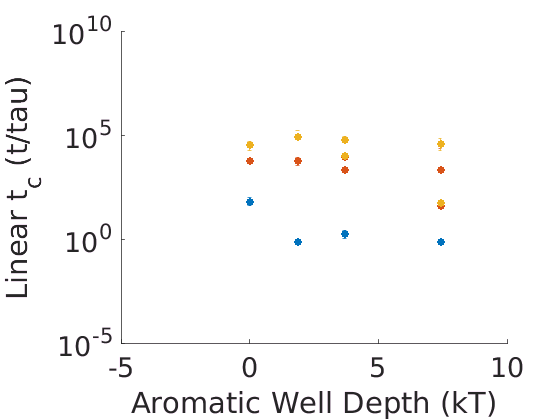

%linear tc
figure()
hold on
errorbar(paramMatrix(:,1),contactMatrix(:,1),contactMatrix(:,2),'.','markersize',20)
errorbar(paramMatrix(:,1),opticalMatrix(:,1),opticalMatrix(:,2),'.','markersize',20)
errorbar(paramMatrix(:,1),alignedMatrix(:,1),alignedMatrix(:,2),'.','markersize',20)
xlabel('Aromatic Well Depth (kT)')
ylabel('Linear t_c (t/tau)')
set(gca,'yscale','log')
set(gca,'fontsize',20)

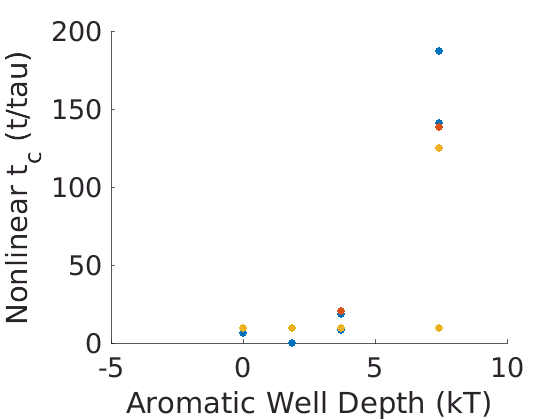

%NL tc
figure()
hold on
errorbar(paramMatrix(:,1),contactMatrix(:,3),contactMatrix(:,4),'.','markersize',20)
errorbar(paramMatrix(:,1),opticalMatrix(:,3),opticalMatrix(:,4),'.','markersize',20)
errorbar(paramMatrix(:,1),alignedMatrix(:,3),alignedMatrix(:,4),'.','markersize',20)
xlabel('Aromatic Well Depth (kT)')
ylabel('Nonlinear t_c (t/tau)')
set(gca,'fontsize',20)

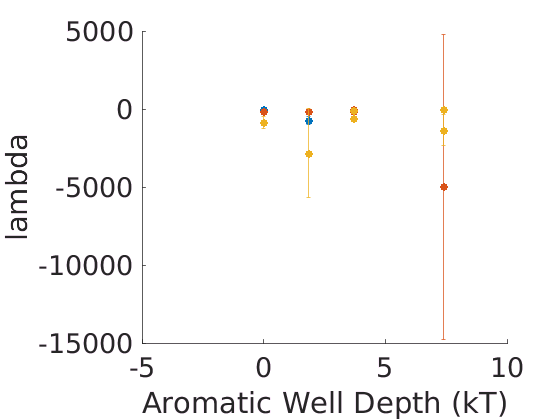

%lambda
figure()
hold on
errorbar(paramMatrix(:,1),contactMatrix(:,5),contactMatrix(:,6),'.','markersize',20)
errorbar(paramMatrix(:,1),opticalMatrix(:,5),opticalMatrix(:,6),'.','markersize',20)
errorbar(paramMatrix(:,1),alignedMatrix(:,5),alignedMatrix(:,6),'.','markersize',20)
xlabel('Aromatic Well Depth (kT)')
ylabel('lambda')
set(gca,'fontsize',20)